# Identification and Estimation Exam (solution)

# December 12, 2023

**Open book, open internet, no communication with human beeing allowed**

This exam is a "matlab live script" : a format that mix text and executable code. Each "section" can be run separately (Tab LIVE EDITOR/Run Section). The outputs is shown on right.

You will be asked:

- to complete, modify and comment matlab code. (into "code" sections)

- to answer literal questions (into "text" sections)

Two parts (Identification and Kalman filer). Finding a correct model (part I) and a correct state estimate (part II.) will secure 12/10. Good comments and discussion will give additional points.

load("exam23data.mat"); %load the data for identification and estimation

# Part I. Identification

The goal is to identify and validate the discrete linear model of a system sampled at $\textrm{Ts}=0\ldotp 1s$. Identification  (rls and els slightly modifed) and validation (computerrors) functions are provided at the end of the code.

## I.1 Load data (this section not supposed to be modified)

A system is excited in three ways:

- a PRBS signal (duration 100s)

- two 211 manoeuvers (duration 100s)

- a simple step input (duration 15s)

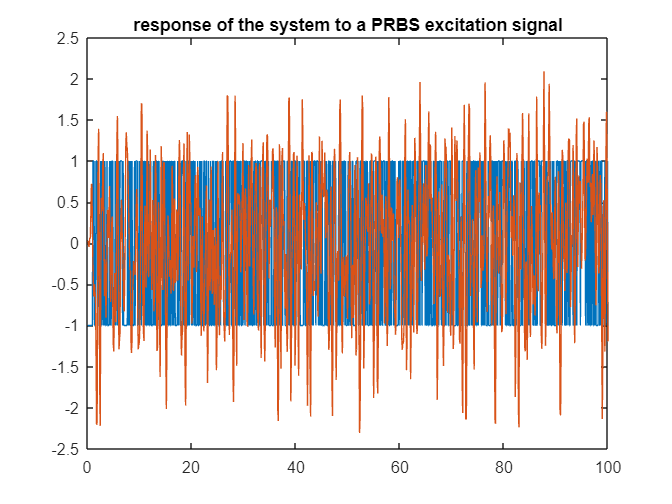

Tprbs = Ts*(1:length(uprbs));
plot(Tprbs,uprbs,Tprbs,yprbs);title('response of the system to a PRBS excitation signal');

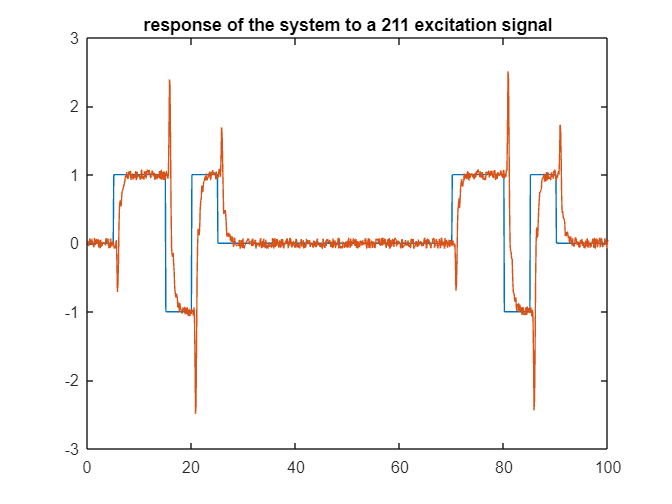

T211 = Ts*(1:length(u211));
plot(T211,u211,T211,y211);title('response of the system to a 211 excitation signal');

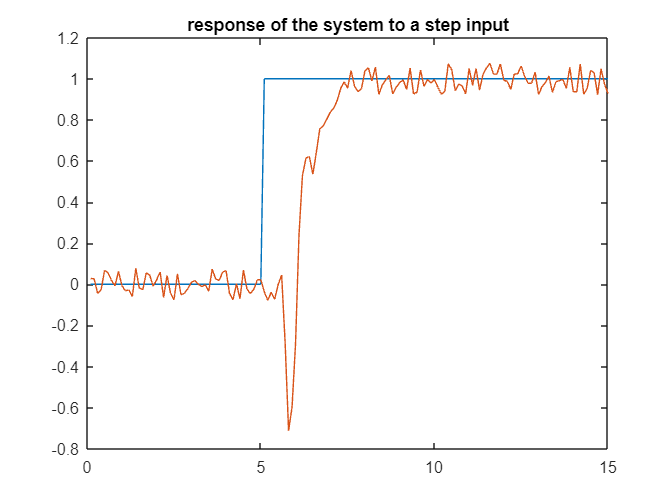

Tstep = Ts*(1:length(ustep));
plot(Tstep,ustep,Tstep,ystep);title('response of the system to a step input');

## I.2 Identification and validation (section to be modified)

You are asked to:

- find the best linear model of the system, based on the RLS and ELS algorithm given below (not supposed to be modified)

- discuss the identification procedure (choice of na,nb,nc,nk,D0,B0,C0)

- discuss the validation procedure and criteria

In the next two sections (I.2.1 and I.2.2) we give the very basic steps of an identification and validation procedure. You will **modify the code** and insert comments in **Text sections**.

### I.2.1 Identification and Validation

The function for each method RLS and ELS including both identification and validation is coded in the function section below. Thes results for each input is displayed below.

**1) PRBS INPUT**

First we consider **Pseudorandom binary sequence(**PRBS) excitation to perform system identification.

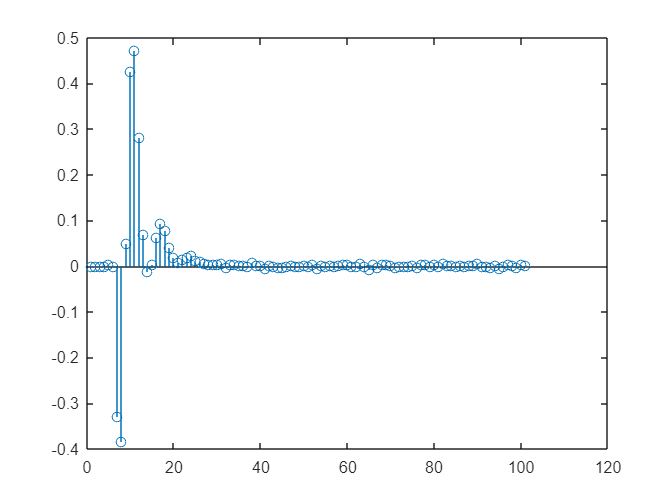

u = uprbs;
y = yprbs;
t = Tprbs;

%Data preparation
N = length(u);
uident = u(1:N/2);
yident = y(1:N/2);
uvalid = u(N/2:end);
yvalid = y(N/2:end);

%Evaluate delay - using impulse response
na = 0;
nb = 100;
nk = 0;
D0 = 10^6*eye(na+nb);
A0 = zeros(na,1);
B0 = zeros(nb,1);
[A,B] = RLS(uident,yident,na,nb,nk,D0,A0,B0);
stem(B)

for i=1:length(B)
    if abs(B(i))>0.04    
       nk=(i-1)-1
       break
   end
end

nk = 5

**We calculate delay with the help of the Finite Impulse Response method, by giving a unit impulse as input to force y(t)=b0+b1+b2+.... . Thus, when we observe the residual of the B vector, we calculate the delay in response. We have calculated nk = (i-1) -1 for two reasons. Firstly we consider (i-1) as the value of i starts from 1. Further we subtract 1 from (i-1) since the first value of B vector can not be calculated due to lack of initial values.**

discrete_time_model_RLS =
 
     -0.3299 z^-6 - 0.3815 z^-7 + 0.05594 z^-8 + 0.4579 z^-9 + 0.5227 z^-10 + 0.2784 z^-11 + 0.05024 z^-12
  -----------------------------------------------------------------------------------------------------------
  1 - 0.007048 z^-1 - 0.005512 z^-2 - 0.09636 z^-3 - 0.04925 z^-4 + 0.03425 z^-5 - 0.1266 z^-6 - 0.09773 z^-7
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -5.9911

na = 7

nb = 7

nk = 5

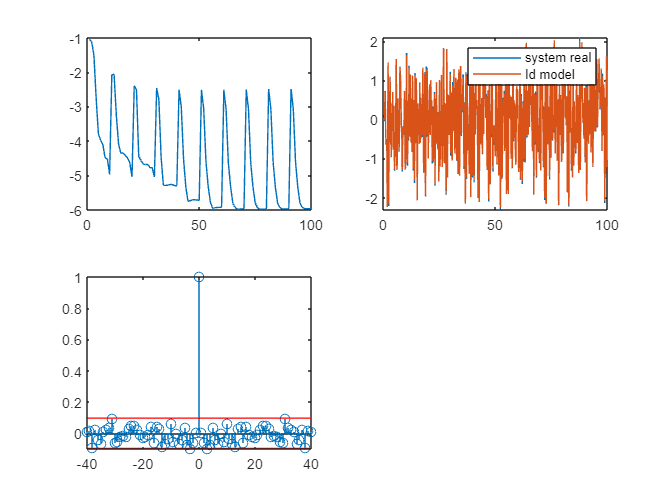

[order1_prbs,AIC1_prbs] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

discrete_time_model_ELS =
 
           -0.3308 z^-6 - 0.08533 z^-7 + 0.3039 z^-8 + 0.273 z^-9 + 0.102 z^-10
  --------------------------------------------------------------------------------------
  1 - 0.8953 z^-1 + 0.277 z^-2 - 0.0171 z^-3 + 0.0396 z^-4 - 0.1268 z^-5 - 0.009597 z^-6
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -6.0215

na = 6

nb = 5

nc = 2

nk = 5

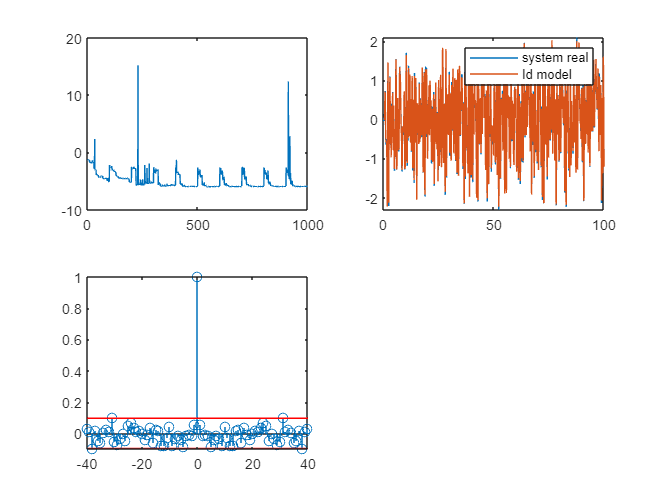

[order2_prbs,AIC2_prbs] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

- **We observe delay of nk=5. **

- **On comparing both methods for PRBS, we observe the model to be na,nb,nk = 7,7,5(na+nb=14) with AIC=-5.99 for RLS method while na, nb,nc,nk =6,5,2,5(na+nb+nc=13) with AIC =-6.02 for ELS method. **

- **The residual obstained from both the methods are also between 0.1 and -0.1. **

- **Therefore, ELS and RLS methods are having showing same effect. **

- **Hence here, ** **the model obtained from the RLS algorithm is sufficient to identify the model as the disturbance is similar to white noise in this case.**

**2) 211 INPUT**

clear all; clc;
load("exam23data.mat"); %load the data for identification and estimation
T211 = Ts*(1:length(u211));
u = u211;
y = y211;
t = T211;

%Data preparation
N = length(u);
uident = u(1:N/2);
yident = y(1:N/2);
uvalid = u(N/2:end);
yvalid = y(N/2:end);

%Evaluate delay - using impulse response
na = 0;
nb = 1000;
nk = 0;
D0 = 10^6*eye(na+nb);
A0 = zeros(na,1);
B0 = zeros(nb,1);
[A,B] = RLS(uident,yident,na,nb,nk,D0,A0,B0);
%stem(B)
for i=1:length(B)
    if abs(B(i))>0.04    
       nk=(i-1)-1
       break
   end
end
nk = 5

nk = 5

discrete_time_model_RLS =
 
     -0.312 z^-6 - 0.4041 z^-7 + 0.0686 z^-8 + 0.4536 z^-9 + 0.5142 z^-10 + 0.2736 z^-11 + 0.07054 z^-12
  ----------------------------------------------------------------------------------------------------------
  1 + 9.152e-05 z^-1 + 0.002387 z^-2 - 0.1002 z^-3 - 0.03424 z^-4 + 0.03582 z^-5 - 0.1343 z^-6 - 0.1051 z^-7
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -6.0077

na = 7

nb = 7

nk = 5

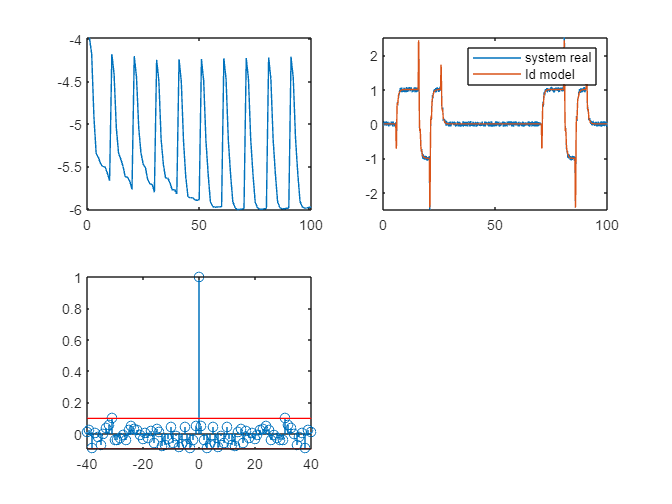

[order1_prbs,AIC1_prbs] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

discrete_time_model_ELS =
 
    -0.3148 z^-6 - 0.1889 z^-7 + 0.3402 z^-8 + 0.3148 z^-9 + 0.155 z^-10
  -------------------------------------------------------------------------
  1 - 0.7113 z^-1 + 0.09677 z^-2 + 0.01399 z^-3 + 0.08746 z^-4 - 0.182 z^-5
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -6.0594

na = 5

nb = 5

nc = 1

nk = 5

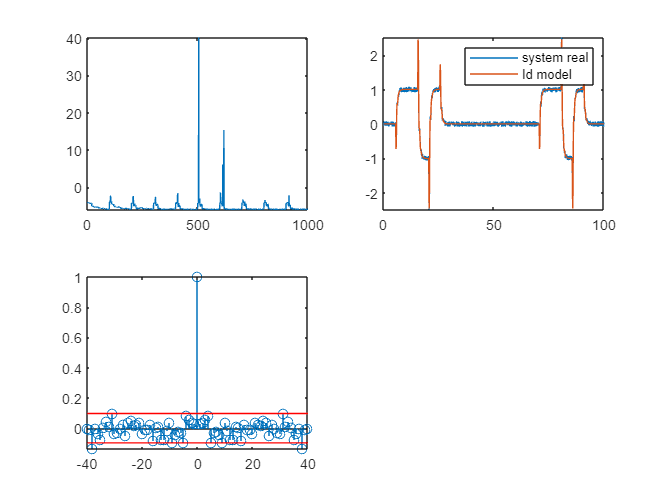

[order2_prbs,AIC2_prbs] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

- **We observe delay of nk=5. **

- **On comparing both methods for 211 input, we observe the model to be na,nb,nk = 7,7,5(na+nb=16) with AIC=-5.9 for RLS method while na, nb,nc,nk =5,5,1,5(na+nb+nc=13) with AIC =-6.02 for ELS method. **

- **The residual obstained from both the methods are also between 0.1 and -0.1, but the residual is less in ELS compared to RLS. **

- **Therefore, ELS method is the better in this case.**

**3) STEP INPUT**

clear all; clc;
load("exam23data.mat"); %load the data for identification and estimation
Tstep = Ts*(1:length(ustep));
u = ustep;
y = ystep;
t = Tstep;

%Data preparation
N = length(u);
uident = u(1:N/2);
yident = y(1:N/2);
uvalid = u(N/2:end);
yvalid = y(N/2:end);

%Evaluate delay - using impulse response
na = 0;
nb = 100;
nk = 0;
D0 = 10^6*eye(na+nb);
A0 = zeros(na,1);
B0 = zeros(nb,1);
[A,B] = RLS(uident,yident,na,nb,nk,D0,A0,B0);
%stem(B)
for i=1:length(B)
    if abs(B(i))>0.04    
       nk=(i-1)-1
       break
   end
end
nk = 5

nk = 5

discrete_time_model_RLS =
 
   -0.2738 z^-6 - 0.3871 z^-7 + 0.2284 z^-8 + 0.378 z^-9 + 0.4546 z^-10 + 0.1041 z^-11
  --------------------------------------------------------------------------------------
  1 - 0.1873 z^-1 - 0.09144 z^-2 - 0.1449 z^-3 + 0.1766 z^-4 - 0.0895 z^-5 - 0.1518 z^-6
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -5.7424

na = 6

nb = 6

nk = 5

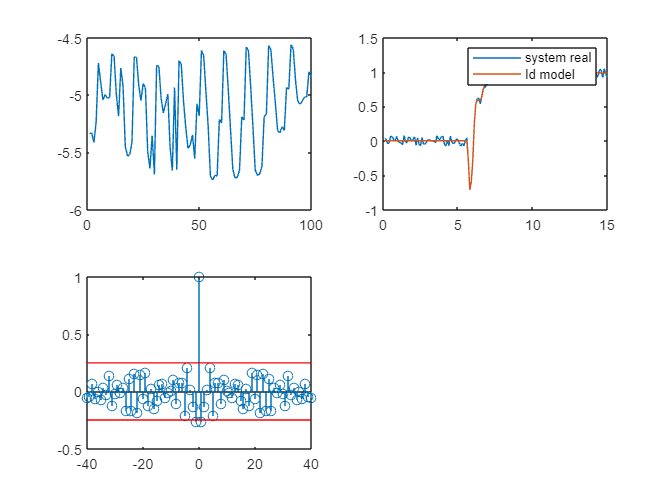

[order1_prbs,AIC1_prbs] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

discrete_time_model_ELS =
 
  -0.2928 z^-6 - 0.2145 z^-7 + 0.428 z^-8 + 0.2224 z^-9 + 0.3101 z^-10 - 0.1844 z^-11
  -----------------------------------------------------------------------------------
                                    1 - 0.7274 z^-1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



minimum_AIC = -5.8507

na = 1

nb = 6

nc = 1

nk = 5

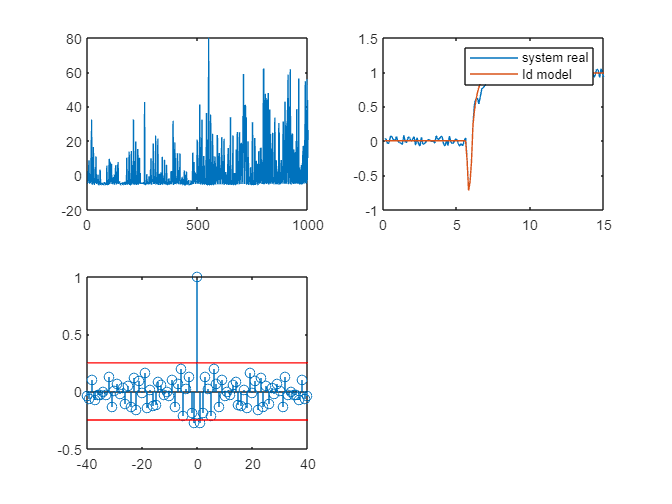

[order2_prbs,AIC2_prbs] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid);

- **We observe delay of nk=5. **

- **On comparing both methods for 211 input, we observe the model to be na,nb,nk = 6,6,5(na+nb=16) with AIC=-5.7 for RLS method while na, nb,nc,nk =1,6,1,5(na+nb+nc=13) with AIC =-5.7 for ELS method. **

- **The residual obstained from both the methods are also between 0.25 and -0.25, but the residual is less in ELS compared to RLS. **

- **Therefore, ELS method is the better in this case.**

### **Conclusion**

**After trying different excitation signals, we conclude that the prbs signal is the best for the following reasons -**

- **We have the low AIC = -6.02 compared to others).**

- **The residuals show bandwidth of -0.1 to 0.1 and the lower order of the system .**

- ** In the prbs case, the RLS is sufficient which takes lesser computation time to identify the model since the disturbance is comparable to white noise. Thus less computation as well.**

# **Part 2. Kalman filtering **

## **2.1 Generate data (section not to be modified)**

A discrete process is driven by the linear discrete equation:


$$\begin{array}{l}
x\left(t+1\right)=0\ldotp 99*\sin \left(x\left(t\right)\right)+e\left(t\right)+v\left(t\right)\\
y\left(t\right)={x\left(t\right)}^2 +w\left(t\right)
\end{array}$$


where :

- $x\left(t\right)$ is the internal state

- $e\left(t\right)$ is a control input

- $v\left(t\right)$ is a zero mean random noise

- $w\left(t\right)$ is a zero mean random noise

In the following code we simulate the output when the input is a pseudo random binary signal. The "real" state x(t) is simulated and will be estimated in the next questions. (This section must be executed before the next ones).

N=500; %number of samples
x = zeros(1,N);
y =zeros(1,N);
e = 0.1*idinput(N,'prbs');% prbs signal

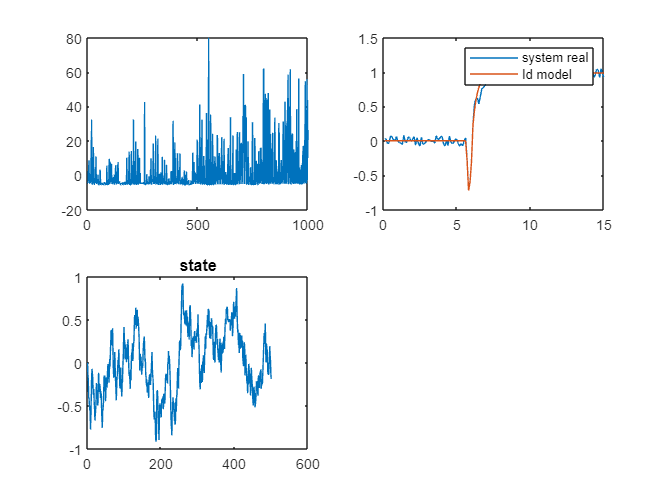

%system noise (v) and measurement noise (w) are coming from the loaded data
%Simulation of the "real" signals with PRBS input
for t=2:N
    %simulate output and internal state
    x(t) = 0.99*sin(x(t-1)) + e(t) + v(t);
    y(t) = x(t)^2 + w(t);
end
plot(1:N,x);title('state');

## 2.1 Kalman filter (section to be modified)

We want to compute the estimate xe(t) of the state x(t) using only the known input e(t) and measured output y(t).

You are asked to:

- code and tune (P,Q,R) your Kalman filter

- discuss the validation procedure and criteria (for the validation you can consider x(t) to be known)

You will **modify the code** and insert comments in **Text sections**.

P=1; %initial value of the filter covariance error (Kalman filter)
Q=0.1; %variance of the additive filter state noise
R=1;%variance of the additive filter measurement noise
xe=0.1; %inial value of the filter estimated state
ypred=0;

for t=2:N

    %estimate the state x(t)

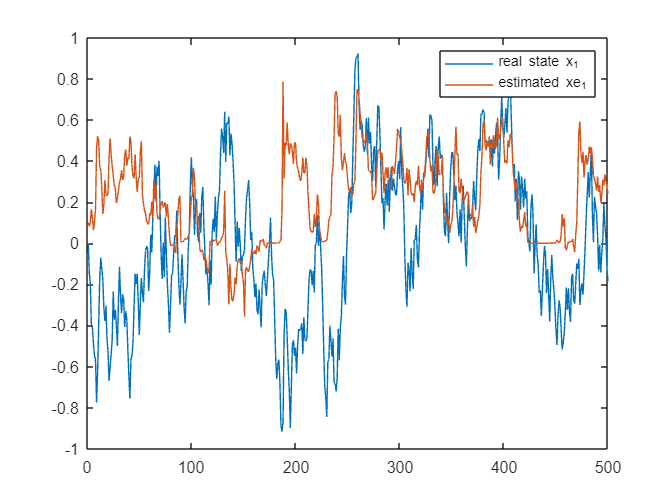

    %your code begins here
    %predict
    xe(t)=0.99*sin(xe(t-1)); %given x = 0.99*sin(x) without noise
    A=0.99*cos(xe(t)); %considering df/dx for x=f(x)

    P=A*P*A'+Q;
    %Update
    ypred(t)=(xe(t))^2; % as y=x^2
    C=2*xe(t); %considering dh/dx for y=h(x)
    K=P*C'*inv(C*P*C'+R);
    P=P-K*C*P;
    xe(t)=xe(t)+K*(y(t)-ypred(t));
    %end of your code
end
close all;
plot(1:N,x,1:N,xe);legend('real state x_1','estimated xe_1');

- **under predict section, **

**xe(t)=0.99*sin(xe(t-1)) as the model is given x = 0.99*sin(x) without noise**

**A=0.99*cos(xe(t)) considering df/dx for x=f(x)**

- **under update section**

**ypred(t)=(xe(t))^2; the given model as y=x^2**

**C=2*xe(t); considering dh/dx for y=h(x)**

- **To tune the parameter**

**we initialize both mean and covariance at 0.1. **

**by initiution be we tune **

P=0.1; %initial value of the filter covariance error (Kalman filter)

Q=0.1; %variance of the additive filter state noise

R=0.001;%variance of the additive filter measurement noise

**Not the best yet. need to be tuned better .**

# Identification and validation functions, not supposed to be modified

## **FUNCTIONS**

**1) RLS ALGORITHM IDENTIFICATION**

function [order,minimum_AIC] = RLSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid)
RLSerrors = [];     %initializing a list to store errors 
RLSsysids = [];     %initializing a list to store system model 
RLSAICs = [];       %initializing a list to store AIC value 
RLSparams = [];     %initializing a list to store parameters na,nb,nk 
for na=1:10           %initializing the loop for parameters na and nb considering from 1 to 10          
    for nb = 1:10
            D0 = 10^6*eye(na+nb);
            A0 = zeros(na,1);
            B0 = zeros(nb,1);
            RLSparams = [RLSparams ; [na nb nk]];   %assigning paramters to the list
            [A,B] = RLS(uident,yident,na,nb,nk,D0,A0,B0);            %solving using RLS algorithm
            [err, J, AIC] = computerrors(uvalid,yvalid,A,B,[]);      %computing the erros and applying AIC criteria
            sysid = tf(B,A,Ts,'variable','z^-1');       %obtainig the tranfer function
            RLSerrors = [RLSerrors ; err'];     %appending obtained error to the list
            RLSAICs(end+1) = AIC;          %appending obtained AIC to the list
            RLSsysids = [RLSsysids ; sysid];    %appending obtained system model to the list
    end
end

%Validation
figure(1);
subplot(2,2,1);
plot([1:na*nb],RLSAICs)   %plot to observe the trend of all AICs
[minimum_AIC,i] = min(RLSAICs);   %collecting minimun AIC value among all computed system ids
discrete_time_model_RLS = RLSsysids(i)    %collecting the system model of the best system with least AIC
minimum_AIC
na = RLSparams(i,1)
nb = RLSparams(i,2)       %observing the parameters at minimum AIC
nk = RLSparams(i,3)
ysim1 = lsim(discrete_time_model_RLS,u,t-t(1));  %Simulating the output for our identified model

subplot(2,2,2);
plot(t,y,t,ysim1)     %observing the difference bw simulated and given output
legend('system real','Id model');
order = [na nb 0];

%Analyse residuals
N1= length(uvalid);
x1 = xcorr(RLSerrors(i,:),RLSerrors(i,:));   %finding correlation
x1 = x1/x1(N1); %nomalizing the correlation
subplot(2,2,3);
stem(-40:1:40,x1(N1-40:N1+40));    %observing the residual graph for chosen model
line([-40 40],[2.17/sqrt(N1) 2.17/sqrt(N1)],'color','r');
line([-40 40],[-2.17/sqrt(N1) -2.17/sqrt(N1)],'color','r');
hold off
end


**2) ELS ALGORITHM IDENTIFICATION**

function [order,minimum_AIC] = ELSID(nk,Ts,u,y,t,uident,yident,uvalid,yvalid)
ELSerrors = [];          %initializing a list to store errors 
ELSsysids = [];         %initializing a list to store system model 
ELSAICs = [];             %initializing a list to store AIC value 
ELSparams = [];        %initializing a list to store parameters na,nb,nc,nk 
for na=1:10
    for nb = 1:10           %initializing the loop for parameters na, nb and nc considering from 1 to 10  
        for nc = 1:10
                D0 = 10^6*eye(na+nb+nc);
                A0 = zeros(na,1);
                B0 = zeros(nb,1);
                C0 = zeros(nc,1);
                ELSparams = [ELSparams ; [na nb nc nk]];      %assigning paramters to the list
                [A,B,C] = ELS(uident,yident,na,nb,nc,nk,D0,A0,B0,C0);        %solving using ELS algorithm
                [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C);          %computing the erros and applying AIC criteria
                sysid = tf(B,A,Ts,'variable','z^-1');           %obtainig the tranfer function
                ELSerrors = [ELSerrors ; err'];             %appending obtained error to the list
                ELSAICs(end+1) = AIC;               %appending obtained AIC to the list
                ELSsysids = [ELSsysids ; sysid];             %appending obtained system model to the list
        end
    end
end

%Validation
figure(2)
subplot(2,2,1);
plot([1:na*nb*nc],ELSAICs)   %plot to observe the trend of all AICs
[minimum_AIC,i] = min(ELSAICs);          %collecting minimun AIC value among all computed system ids
discrete_time_model_ELS = ELSsysids(i)       %collecting the system model of the best system with least AIC
minimum_AIC
na = ELSparams(i,1)
nb = ELSparams(i,2)
nc = ELSparams(i,3)         %observing the parameters at minimum AIC
nk = ELSparams(i,4)
ysim2 = lsim(discrete_time_model_ELS,u,t-t(1));    %Simulating the output for our identified model
subplot(2,2,2);
plot(t,y,t,ysim2)            %observing the difference bw simulated and given output
legend('system real','Id model');
order = [na nb nc];

%Analyse residuals
N2 = length(uvalid);
x2 = xcorr(ELSerrors(i,:),ELSerrors(i,:));           %finding correlation
x2 = x2/x2(N2);              %nomalizing the correlation
subplot(2,2,3);
stem(-40:1:40,x2(N2-40:N2+40));                 %observing the residual graph for chosen model
line([-40 40],[2.17/sqrt(N2) 2.17/sqrt(N2)],'color','r');
line([-40 40],[-2.17/sqrt(N2) -2.17/sqrt(N2)],'color','r');
end

### Recursive Least Square

function [A,B] = RLS(uid,yid,na,nb,nk,D0,A0,B0)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
% theta = zeros(na+nb,1);
theta = [A0;B0];
% D = 10^6*eye(na+nb);
D = D0;
%Recursive algorithm
for t = max([na nb+nk]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1)];
    yhatprior = theta'*phi;
    eps0 = yid(t+1)-yhatprior;
    epsposterior = eps0/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior;
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end
A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
end

### Recursive Extended Least Square

function [A,B,C] = ELS(uid,yid,na,nb,nc,nk,D0,A0,B0,C0)
uid = reshape(uid,[],1);
yid = reshape(yid,[],1);
%initialization
% theta = zeros(na+nb+nc,1);
theta = [A0;B0;C0];
% D = 10^6*eye(na+nb+nc);
D = D0;
epsposterior = zeros(length(yid),1);
eps0 = zeros(length(yid),1);
%Recursive algorithm
for t = max([na nb+nk nc]):(length(yid)-1)
    phi = [-yid(t:-1:t-na+1);uid(t-nk:-1:t-nb-nk+1);epsposterior(t:-1:t-nc+1)];
    yhatprior = theta'*phi;
    eps0(t+1) = yid(t+1)-yhatprior;
    epsposterior(t+1) = eps0(t+1)/(1+phi'*D*phi);
    theta = theta + D*phi*epsposterior(t+1);
    D = D - D*phi*phi'*D/(1+phi'*D*phi);
end

A = [1;theta(1:na)]';
B = [zeros(nk+1,1);theta(na+1:na+nb)]';
C = theta(na+nb+1:end)';
end

### Prediction Error and AIC criteria

function [err, J, AIC] = computerrors(uvalid,yvalid,A,B,C)
N = length(uvalid);
if nargin == 4
    C = [];
end
uvalid = reshape(uvalid,[],1);
yvalid = reshape(yvalid,[],1);
A = A(2:end);
B = B(2:end);
na=length(A);
nb=length(B);
nc=length(C);
theta = [A';B';C'];
err = zeros(N,1);
%Recursive algorithm
for t = max([na nb nc]):(length(yvalid)-1)
    phi = [-yvalid(t:-1:t-na+1);uvalid(t:-1:t-nb+1);err(t:-1:t-nc+1)];
    err(t+1) = yvalid(t+1)-theta'*phi;
end
J = 1/N*(err'*err);
AIC = log(J)+2*(na+nb+nc)/N;
end